# Combining spatial enhancement methods to improve image

Steps in the processing:

- Apply laplacian filter to image & add it to original image.

- Find original image gradient using Sobel filters.

- Smooth the gradient of image with box filter.

- Array multiplication of image laplacian & smoothed gradient.

- Finally add the product of last step to original image.

Combined formula:

                
$$g(x,y) = f(x,y) +

\biggl [
  \Bigl [
    f(x,y) + \nabla ^ 2 f(x,y)
  \Bigr ]

  \cdot

  \Bigl [
    w(x,y) \star M(x,y)
  \Bigr ]
\biggr ]
$$


where $M(x,y)$ is image gradient and $w(x,y)$ is the box filter.

## Original image

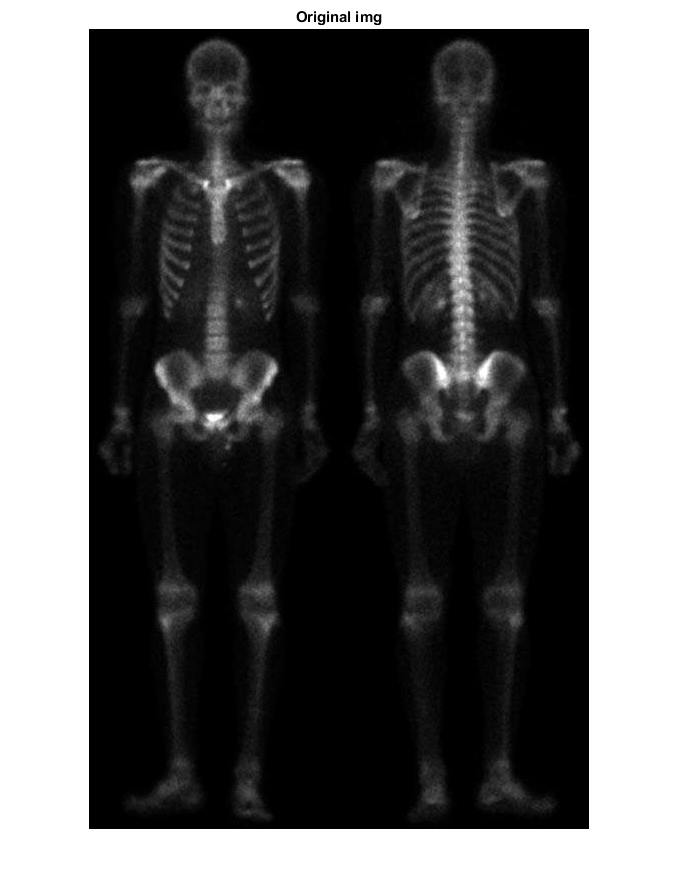

img = im2double(imread('skeleton.tif'));
showimg(img, 'Original img');

## Defining filters

We've Laplacian filter, Sobel filters for image gradient and box filter for averaging.

filter_laplacian = -[1 1 1; 1 -8 1; 1 1 1];
filter_sobel_x = [-1 -2 -1; 0 0 0; 1 2 1];
filter_sobel_y = [-1 0 1; -2 0 2; -1 0 1];
filter_box = ones([5 5])./25;

## 1. Sharpning image with Laplacian

First we'll sharpen our image using Laplacian filter. To do that we'll first apply Laplacian filter to image. And then add the filtered to original image.

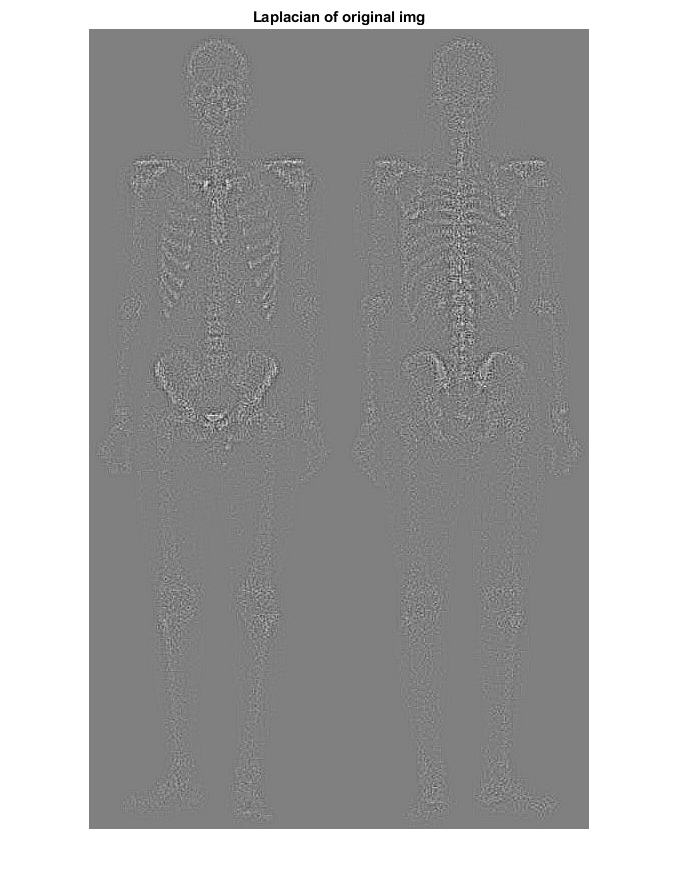

img_laplacian = imfilter(img, filter_laplacian);
showimg(img_laplacian, 'Laplacian of original img');

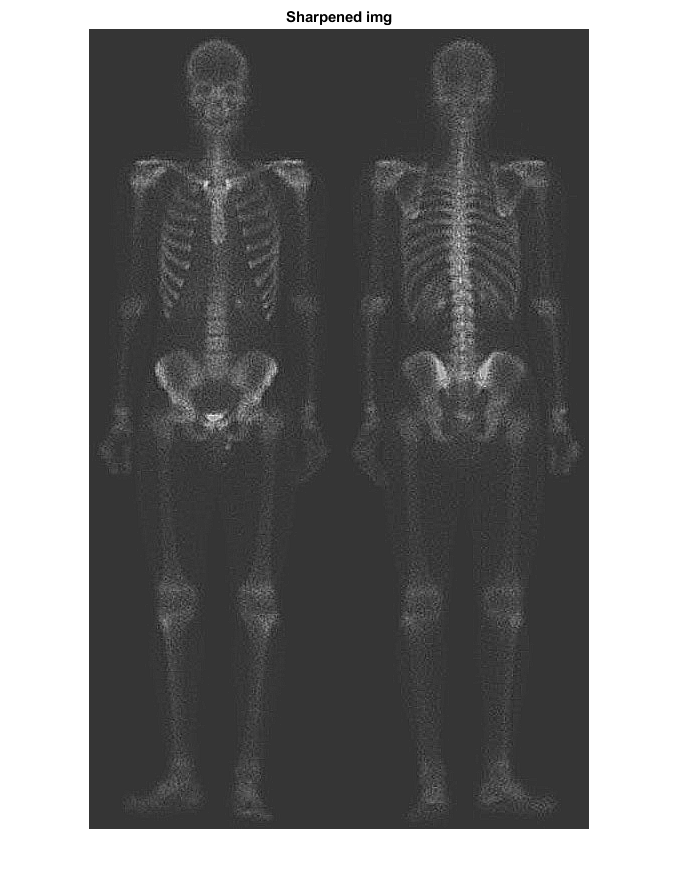

img_sharpened_with_laplacian = img + img_laplacian;
showimg(img_sharpened_with_laplacian, 'Sharpened img');

## 2. Finding Gradient with Sobel

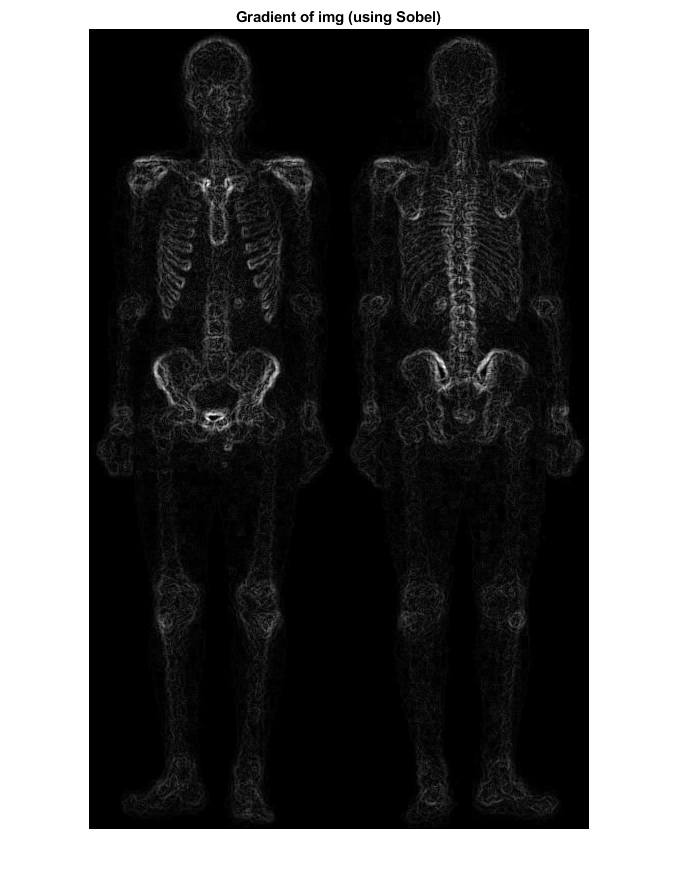

img_x_gradient = imfilter(img, filter_sobel_x);
img_y_gradient = imfilter(img, filter_sobel_y);
img_gradient = abs(img_x_gradient) + abs(img_y_gradient);
showimg(img_gradient, 'Gradient of img (using Sobel)');

## 3. Smoothning of Gradient

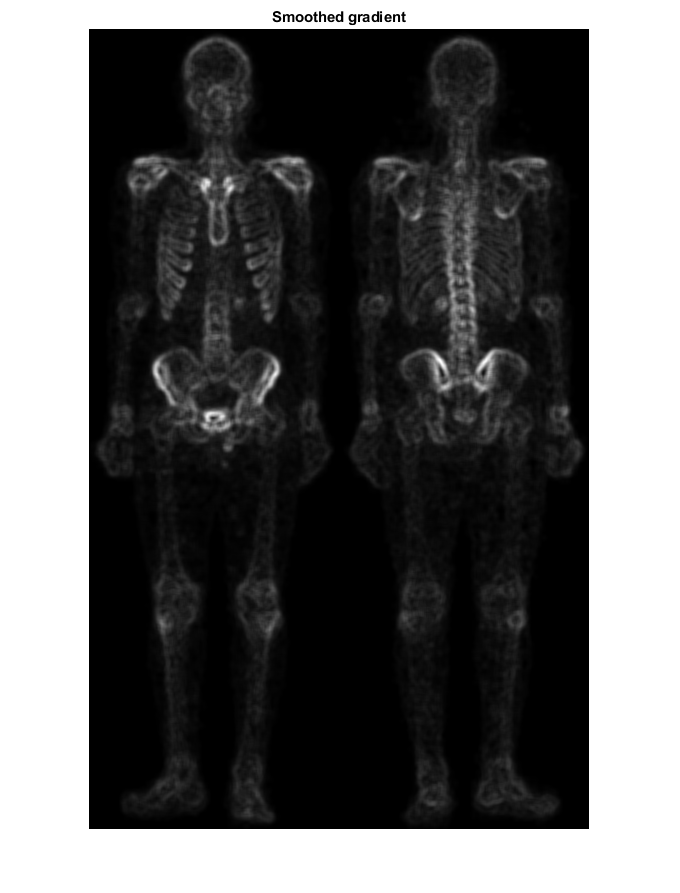

img_smoothed_gradient = imfilter(img_gradient, filter_box);
showimg(img_smoothed_gradient, 'Smoothed gradient');

## 4. Product of laplacian & smoothed gradient

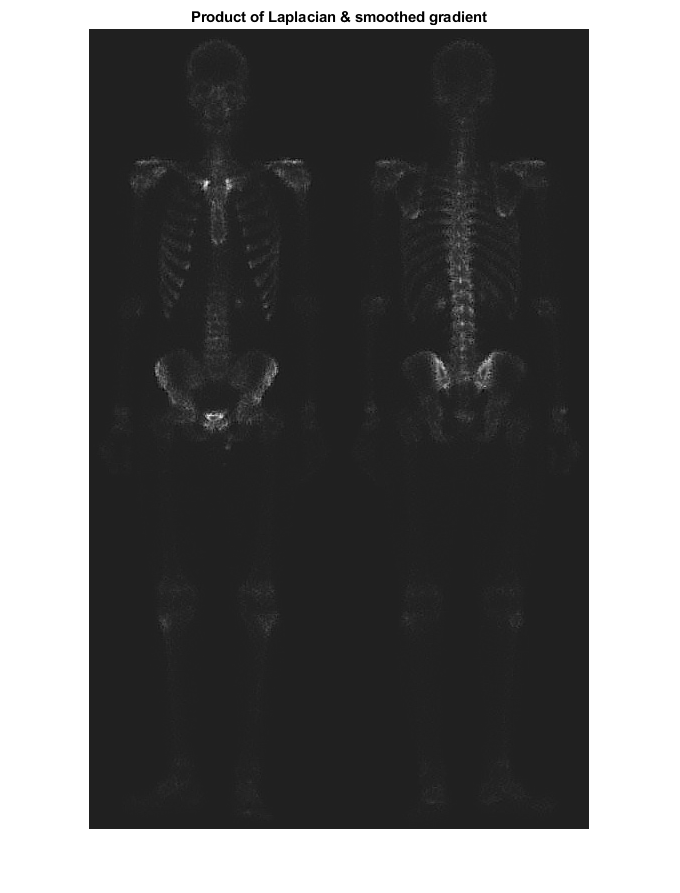

img_laplacian_and_smoothed_gradient_product = img_smoothed_gradient .* img_sharpened_with_laplacian;
showimg(img_laplacian_and_smoothed_gradient_product, 'Product of Laplacian & smoothed gradient');

## 5. Adding product of image laplacian with smoothed gradient to original image

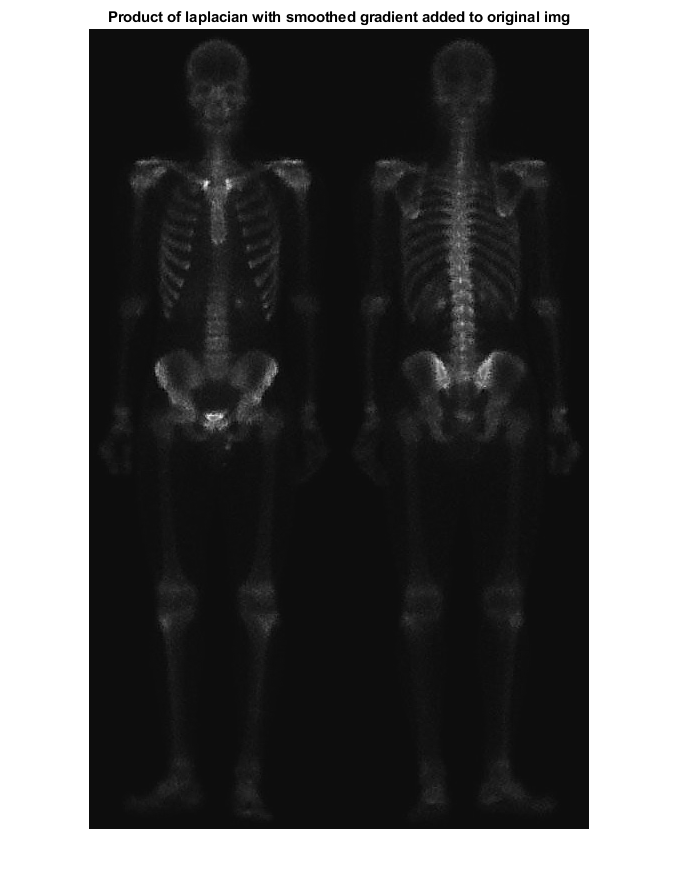

img_final = img + img_laplacian_and_smoothed_gradient_product;
showimg(img_final, 'Product of laplacian with smoothed gradient added to original img')

## Changing final image with Gamma transformation

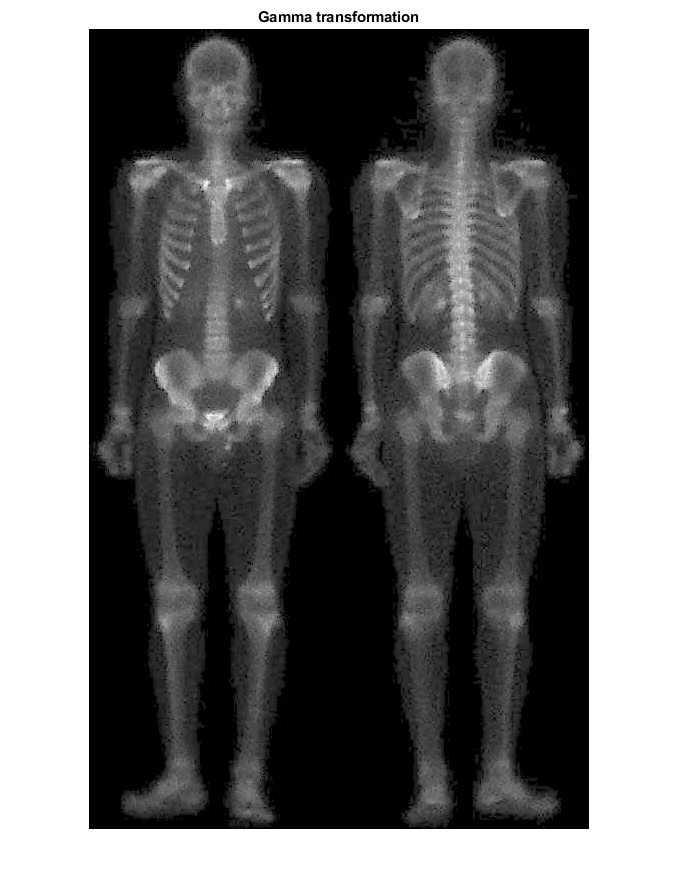

gamma =0.355;
img_gamma = img_final .^ gamma;
showimg(img_gamma, 'Gamma transformation');

## Show image function

function showimg(img, img_title)
    imshow(img, []);
    title(img_title);
end